T0 = [1,0,0,0;
    0,1,0,0;
    0,0,1,0;
    0,0,0,1];

alpha1 = 90 / 180 * pi;
T1 = dh_transform(0, 0, 45,theta1);
T2 = dh_transform(alpha1, 126,0,0);
trial1 = T0 * T1

trial1 =     0.0000   -1.0000         0         0
    1.0000    0.0000   -0.0000         0
         0         0    1.0000   45.0000
         0         0         0    1.0000




first_two_sim = T0 * T1 * T2

first_two_sim =     0.0000   -0.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000  126.0000
         0    1.0000    0.0000   45.0000
         0         0         0    1.0000


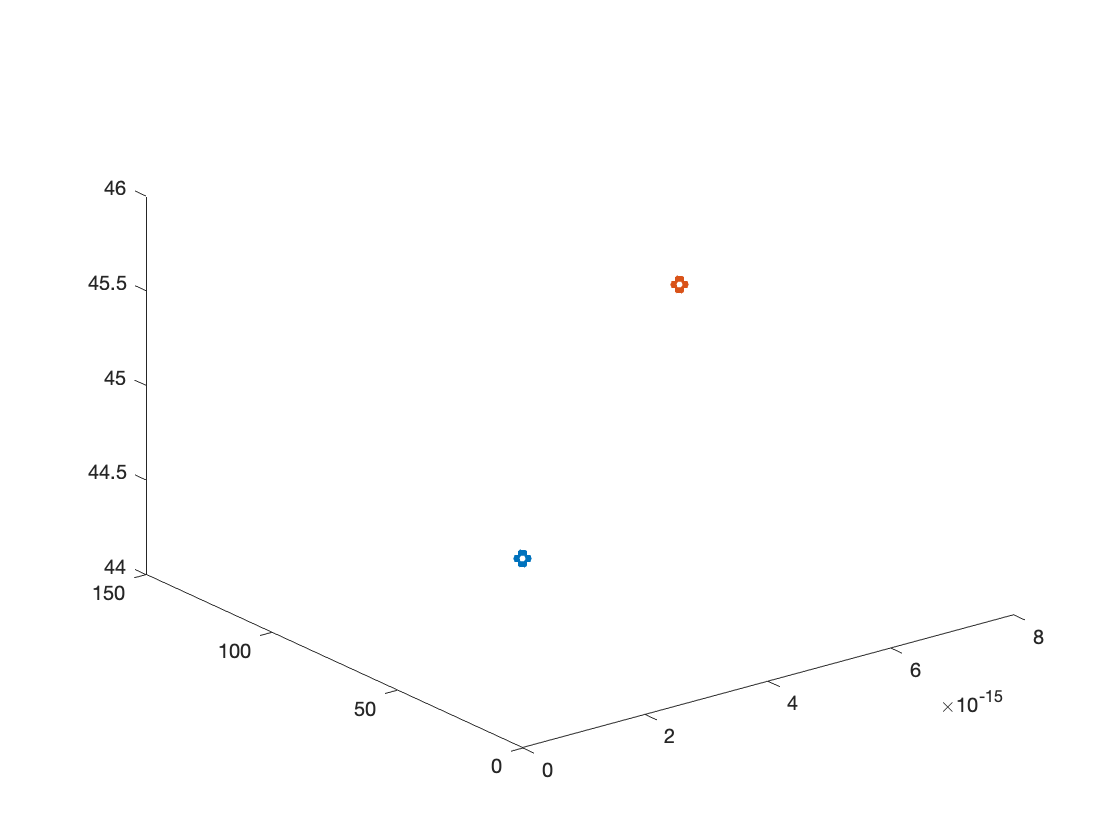

temp1 = trial1(:,4);
x1 = temp1(1);
y1 = temp1(2);
z1 = temp1(3);
temp2 = first_two_sim(:,4);
x2= temp2(1);
y2 = temp2(2);
z2 = temp2(3);
plot3(x1,y1,z1, "o", "LineWidth",3);
hold on
plot3(x2,y2,z2,"o", "LineWidth",3);